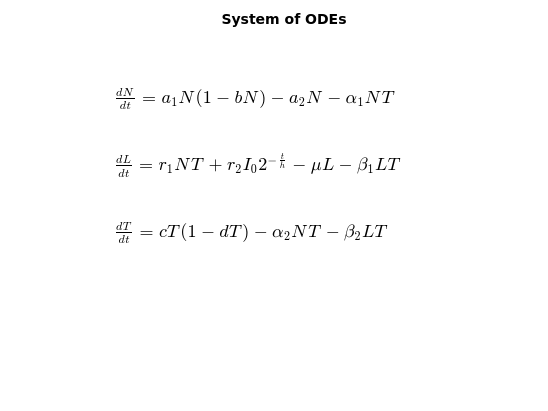

% Arbitrary_1 %

clc; clear; close all;

% Solve the system of ODEs %

% Define parameter values %
a1 = 1.0;  
b = 0.1;  
a2 = 0.2;  
alpha1 = 0.3;  
r1 = 0.4;  
r2 = 0.5;  
I0 = 1.0;  
h = 1.0;  
mu = 0.6;  
beta1 = 0.7;  
c = 0.8;  
d = 0.9;  
alpha2 = 0.1;  
beta2 = 0.2;  

% Initial conditions %
N0 = 1;
L0 = 1;
T0 = 1;
y0 = [N0; L0; T0];

% Time span %
tspan = [0 100];

% Solve using ode45 %
[t, y] = ode45(@(t, y) systemODEs(t, y, a1, b, a2, alpha1, r1, r2, I0, h, mu, beta1, c, d, alpha2, beta2), tspan, y0);

% Extract solutions %
N = y(:,1);
L = y(:,2);
T = y(:,3);

% Confirmation of the System of Ordinary Differential Equations %
figure;
axis off;

eq1 = '$\frac{dN}{dt} = a_1 N(1 - bN) - a_2 N - \alpha_1 N T$';
eq2 = '$\frac{dL}{dt} = r_1 N T + r_2 I_0 2^{-\frac{t}{h}} - \mu L - \beta_1 L T$';
eq3 = '$\frac{dT}{dt} = c T(1 - d T) - \alpha_2 N T - \beta_2 L T$';

text(0.1, 0.8, eq1, 'Interpreter', 'latex', 'FontSize', 14);
text(0.1, 0.6, eq2, 'Interpreter', 'latex', 'FontSize', 14);
text(0.1, 0.4, eq3, 'Interpreter', 'latex', 'FontSize', 14);

title('System of ODEs');

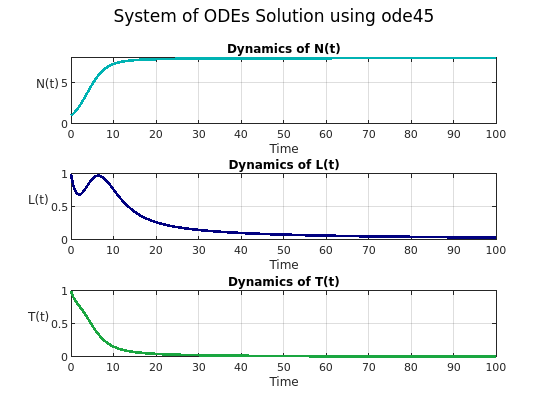


% Plot the results %

figure;
subplot(3,1,1);
plot(t, N, 'Color', [0, 0.7, 0.7], 'LineWidth', 2); 
xlabel('Time'); ylabel('N(t)', 'Rotation', 0, 'HorizontalAlignment', 'right');
title('Dynamics of N(t)');
grid on;

subplot(3,1,2);
plot(t, L, 'Color', [0, 0, 0.5], 'LineWidth', 2); 
xlabel('Time'); ylabel('L(t)', 'Rotation', 0, 'HorizontalAlignment', 'right');
title('Dynamics of L(t)');
grid on;

subplot(3,1,3);
plot(t, T, 'Color', [0.10 0.65 0.25], 'LineWidth', 2); 
xlabel('Time'); ylabel('T(t)', 'Rotation', 0, 'HorizontalAlignment', 'right');
title('Dynamics of T(t)');
grid on;

sgtitle('System of ODEs Solution using ode45');

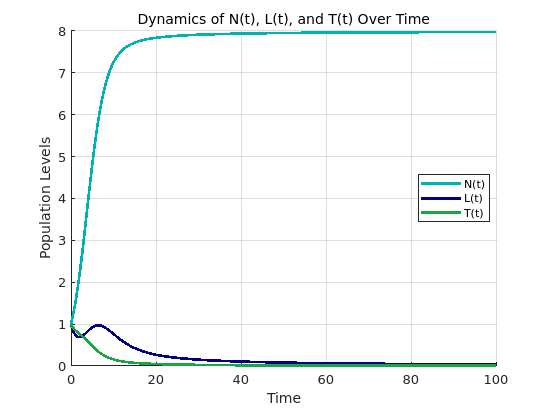


% Plot the dynamics of all three variables in one figure with three curves

figure;
hold on;
plot(t, N, 'Color', [0, 0.7, 0.7], 'LineWidth', 2);  % N(t)
plot(t, L, 'Color', [0, 0, 0.5], 'LineWidth', 2);    % L(t)
plot(t, T, 'Color', [0.10 0.65 0.25], 'LineWidth', 2); % T(t)
hold off;

xlabel('Time');
ylabel('Population Levels');
title('Dynamics of N(t), L(t), and T(t) Over Time', 'FontWeight', 'normal');
legend('N(t)', 'L(t)', 'T(t)', 'Location', 'Best');
grid on;

function dydt = systemODEs(t, y, a1, b, a2, alpha1, r1, r2, I0, h, mu, beta1, c, d, alpha2, beta2)
    N = y(1);
    L = y(2);
    T = y(3);
    
    dNdt = a1 * N * (1 - b * N) - a2 * N - alpha1 * N * T;
    dLdt = r1 * N * T + r2 * I0 * 2^(-t / h) - mu * L - beta1 * L * T;
    dTdt = c * T * (1 - d * T) - alpha2 * N * T - beta2 * L * T;
    
    dydt = [dNdt; dLdt; dTdt];
end
